% 1. Leggi immagine originale
i = imread("test.jpg");
i_double = im2double(i);

% 2. Aggiungi rumore speckle
j = imnoise(i_double, "speckle", 0.01);

% 3. Prealloca immagine filtrata
j_filtered = zeros(size(j));

% 4. Applica filtro Wiener canale per canale (finestra 5x5)
for c = 1:3
    j_filtered(:,:,c) = wiener2(j(:,:,c), [3 3]);
end

% 5. Calcola PSNR
psnr_noisy = psnr(j, i_double);
psnr_filtered = psnr(j_filtered, i_double);

% 6. Visualizza risultati
fprintf("PSNR immagine rumorosa: %.2f dB\n", psnr_noisy);

PSNR immagine rumorosa: 28.54 dB


fprintf("PSNR dopo filtro Wiener: %.2f dB\n", psnr_filtered);

PSNR dopo filtro Wiener: 33.01 dB


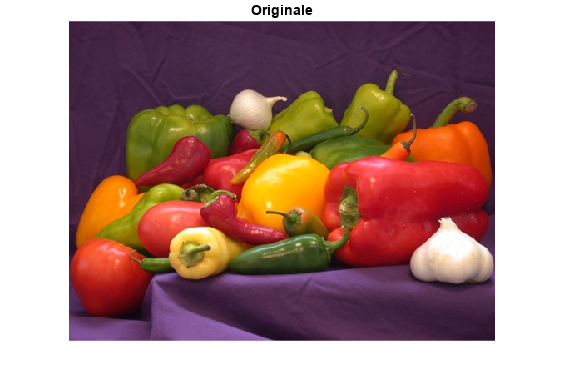


figure;
imshow(i_double), title("Originale");

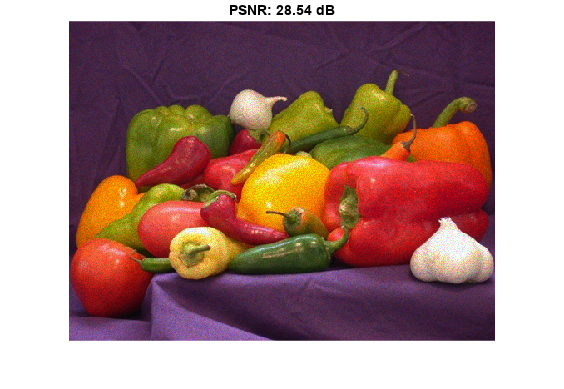

imshow(j), title(sprintf("Rumorosa\nPSNR: %.2f dB", psnr_noisy));

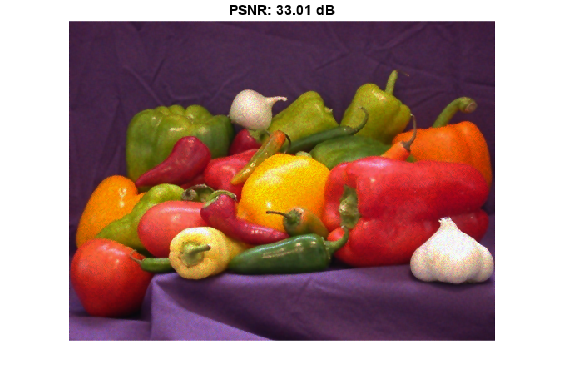

imshow(j_filtered), title(sprintf("Filtro Wiener\nPSNR: %.2f dB", psnr_filtered));